# COMSA Project LoRa-MODBUS product-reliability testing

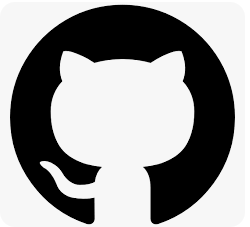 [GitHub URL of the livescript](https://github.com/erdemcanaz/MODBUS/tree/development/matlab)

## Introduction

The objective of this subpart of the project was to develop a wireless device control system based on LoRa technology that can be used to control MODBUS supporting devices. To achieve this goal, a custom-designed printed circuit board (PCB) was assembled, and software was developed to enable the control and logging of the entire system. However, in order to ensure the reliability of the system, it was essential to validate its success rate. Given that each communication has a possibility of failure, a test setup was devised and implemented, with the system running continuously for 12 hours in a machine laboratory. At the conclusion of the testing, the results demonstrated that the success rate of the system was more than acceptable. 

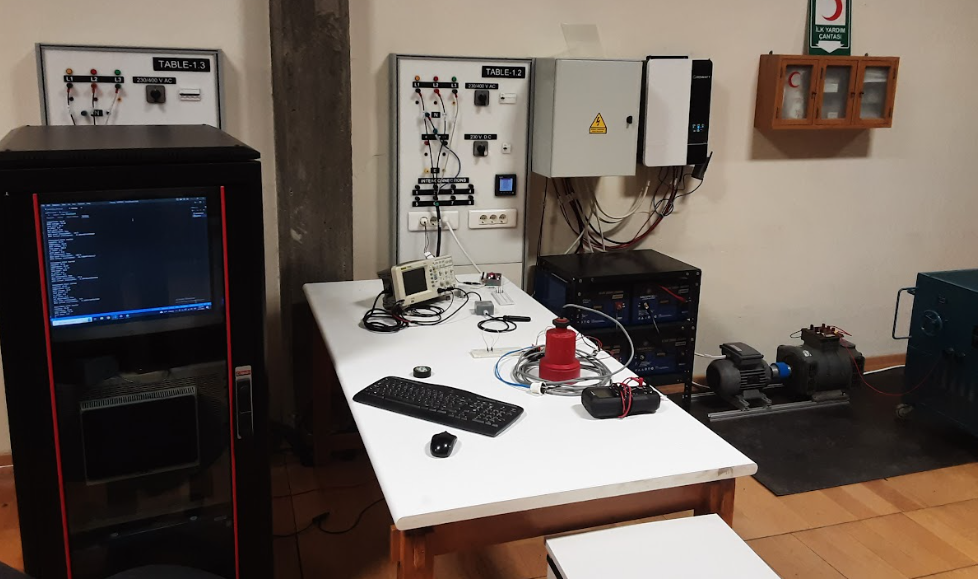

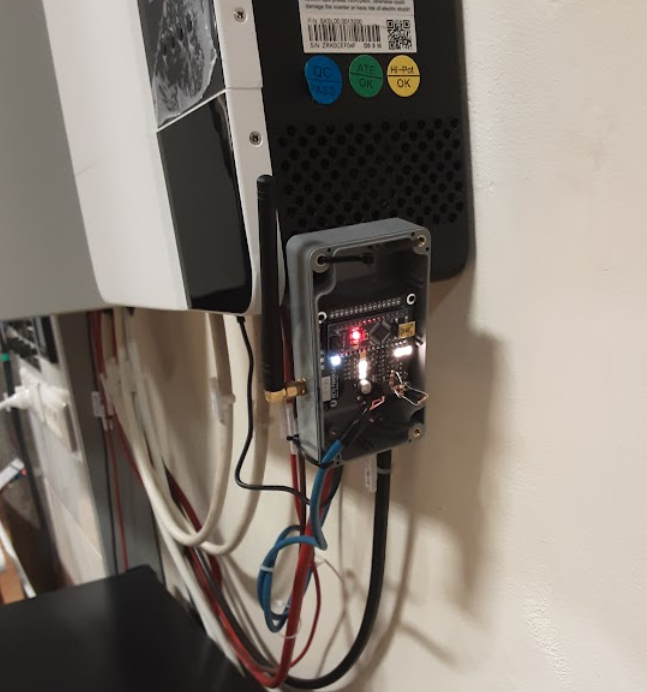 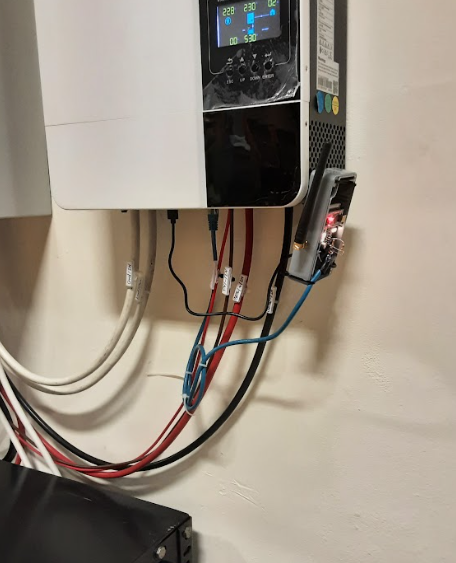 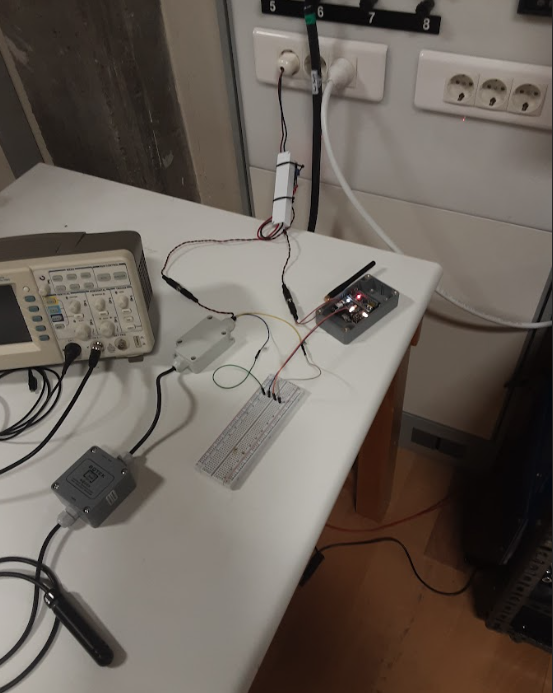

## Remarks

- **BESS voltage** is measured instead of **Load Power **as seen in the below figure**. **This issue is solved and commited. However, this correction is valid in this report.

- `The CSV file used in this report consists of 10 columns`. An additional field, called the **"Device tag"** was added to personalize the devices. For example, if a BQ225 sensor is placed on the rooftop, the device tag can be set as "rooftop BQ225." This was done to ensure that during the filtering process, it is clear which device is being referred to. Using only the device model for filtering purposes was insufficient, as there could be multiple devices of the same model. Be sure that in future, the data filtering function  `filter_data(csv_table, s_date, e_date, device_name, tag)` is corrected.

## Csv visualization:

### I. Clean up

close all
clearvars
clc

### **II. CSV import**

The data is imported from a .csv file, which contains the following columns:

- Year

- Month

- Day

- Hour

- Minute

- Second

- Operation tag (sensor, inverter, VFD, etc.)

- Device model (BQ225, Nivelco, etc.)

- Device tag (e.g., "One at the greenhouse," "machine laboratory," etc.)

- Tag (e.g., humidity, grid power, load power, etc.)

- Value (e.g., 23.256, 1.235216, "text," etc.).

These columns represent various aspects of the data being collected, including the date and time of the measurement, the type of operation being performed (e.g., sensing, inverting, etc.), the device model and tag, as well as the specific measurement being taken and its corresponding value.

csv_file_name = 'default_2_20_04_2023.csv';
table = readtable(csv_file_name);

### **III. Filtering & Postprocessing**

In this section of the project, the collected data is filtered based on the start and end dates, as well as the device model and tag. Once the data has been filtered, it is processed to calculate the success probability of each type of measurement and the total number of packages sent.

By performing these calculations, we are able to gain insight into the overall reliability and efficiency of the system. This information can then be used to make improvements and optimizations as needed, in order to further enhance the performance of the system.

%filter data
start_date =  [2022,4,19,13,35,48];
end_date =  [2023,4,21,23,59,59];

[humidity,t_humidity, humidity_c, t_humidity_c] = filter_data(table,start_date , end_date, "BQ225","humidity");
[temperature,t_temperature, temperature_c, t_temperature_c] = filter_data(table,start_date , end_date, "BQ225","temperature");

[BESS_voltage,t_BESS_voltage, BESS_voltage_c, t_BESS_voltage_c] = filter_data(table,start_date , end_date, "GROWATT_SPF5000_ES","BESS-voltage");
[load_power,t_load_power, load_power_c, t_load_power_c] = filter_data(table,start_date , end_date, "GROWATT_SPF5000_ES","load-power");
[pv_power,t_pv_power, pv_power_c, t_pv_power_c] = filter_data(table,start_date , end_date, "GROWATT_SPF5000_ES","pv-power");
[calculated_BESS_power,t_calculated_BESS_power, calculated_BESS_power_c, t_calculated_BESS_power_c] = filter_data(table,start_date , end_date, "GROWATT_SPF5000_ES","calculated-BESS-power");
[calculated_BESS_current,t_calculated_BESS_current, calculated_BESS_current_c, t_calculated_BESS_current_c] = filter_data(table,start_date , end_date, "GROWATT_SPF5000_ES","calculated-BESS-current");

%%Postprocess data for succes probabilities

%humidity
total_packages_humidity = size(humidity,2)+size(humidity_c,2);
succesfull_packages = size(humidity,2);
succes_probability_humidity = succesfull_packages/total_packages_humidity;

% temperature
total_packages_temperature = size(temperature,2)+size(temperature_c,2);
succesfull_packages = size(temperature,2);
succes_probability_temperature = succesfull_packages/total_packages_temperature;

% BESS voltage
total_packages_BESS_voltage = size(BESS_voltage,2)+size(BESS_voltage_c,2);
succesfull_packages = size(BESS_voltage,2);
succes_probability_BESS_voltage = succesfull_packages/total_packages_BESS_voltage;

% load power
total_packages_load_power = size(load_power,2)+size(load_power_c,2);
succesfull_packages = size(load_power,2);
succes_probability_load_power = succesfull_packages/total_packages_load_power;

% PV power
total_packages_pv_power = size(pv_power,2)+size(pv_power_c,2);
succesfull_packages = size(pv_power,2);
succes_probability_pv_power = succesfull_packages/total_packages_pv_power;

% calculated BESS power
total_packages_BESS_power = size(calculated_BESS_power,2)+size(calculated_BESS_power_c,2);
succesfull_packages = size(calculated_BESS_power,2);
succes_probability_calculated_BESS_power = succesfull_packages/total_packages_BESS_power;

% calculated BESS current
total_packages_BESS_current = size(calculated_BESS_current,2)+size(calculated_BESS_current_c,2);
succesfull_packages = size(calculated_BESS_current,2);
succes_probability_calculated_BESS_current = succesfull_packages/total_packages_BESS_current;

    

### **IV. Data plots**

In this section of the project, the different types of data collected from the system are plotted with respect to time. This allows us to visually analyze the behavior and trends of each type of measurement over the course of the data collection period.

By plotting the data in this way, we can identify any patterns or anomalies that may be present, such as spikes or dips in measurements. This information can then be used to troubleshoot any issues that may be impacting the performance of the system, as well as to make informed decisions about any necessary adjustments or improvements.

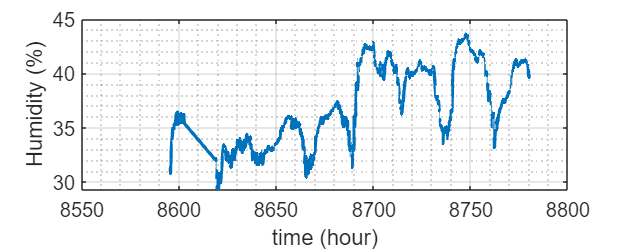

plot_size_x = 750;
plot_size_y = 300;
figure
set(gcf, 'Position', [100, 100, plot_size_x, plot_size_y])
plot(t_humidity./3600, humidity,'LineWidth',2)
ylabel('Humidity (%)')
xlabel('time (hour)')
set(gca,'FontSize',12)
grid on
grid minor

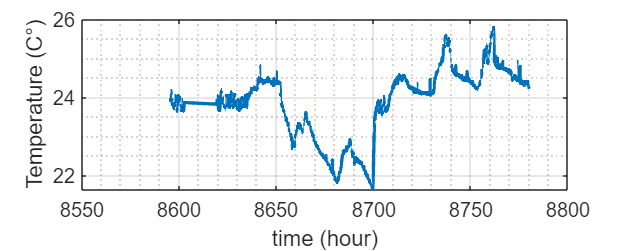

figure
set(gcf, 'Position', [100, 100, plot_size_x, plot_size_y])
plot(t_temperature./3600, temperature,'LineWidth',2)
ylabel('Temperature (C°)')
xlabel('time (hour)')
set(gca,'FontSize',12)
grid on
grid minor

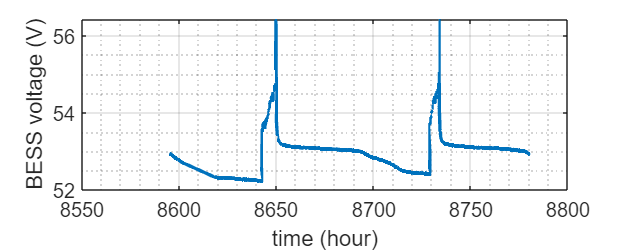

figure
set(gcf, 'Position', [100, 100, plot_size_x, plot_size_y])
plot(t_BESS_voltage./3600,BESS_voltage,'LineWidth',2)
ylabel('BESS voltage (V)')
xlabel('time (hour)')
set(gca,'FontSize',12)
grid on
grid minor

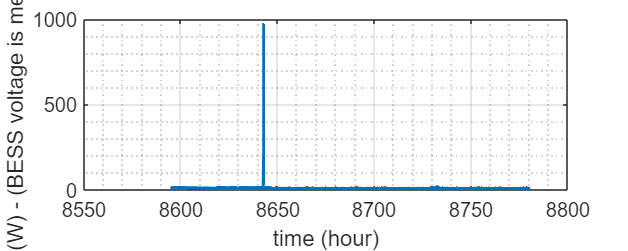

figure
set(gcf, 'Position', [100, 100, plot_size_x, plot_size_y])
plot(t_load_power./3600,load_power,'LineWidth',2)
ylabel('Load power (W) - (BESS voltage is measured instead) ')
xlabel('time (hour)')
set(gca,'FontSize',12)
grid on
grid minor

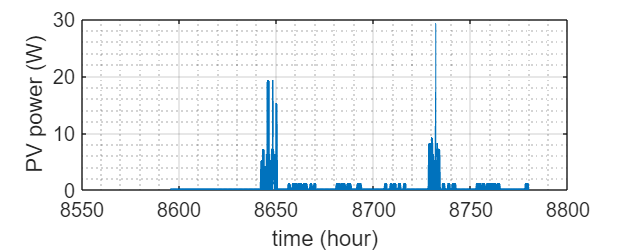

figure
set(gcf, 'Position', [100, 100, plot_size_x, plot_size_y])
plot(t_pv_power./3600,pv_power,'LineWidth',2)
ylabel('PV power (W)')
xlabel('time (hour)')
set(gca,'FontSize',12)
grid on
grid minor

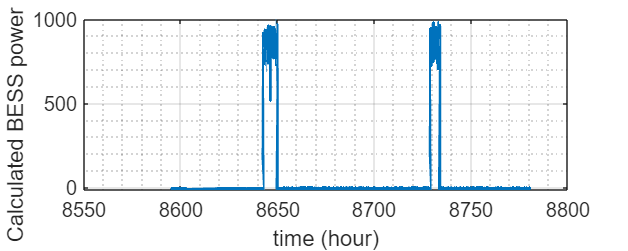

figure
set(gcf, 'Position', [100, 100, plot_size_x, plot_size_y])
plot(t_calculated_BESS_power./3600,calculated_BESS_power,'LineWidth',2)
ylabel('Calculated BESS power (W)')
xlabel('time (hour)')
set(gca,'FontSize',12)
grid on
grid minor

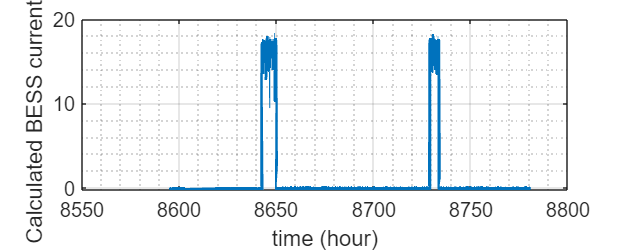

figure
set(gcf, 'Position', [100, 100, plot_size_x, plot_size_y])
plot(t_calculated_BESS_current./3600,calculated_BESS_current,'LineWidth',2)
ylabel('Calculated BESS current (A)')
xlabel('time (hour)')
set(gca,'FontSize',12)
grid on
grid minor

## Succes rate

In this section of the project, the success rate of the data transmission system is analyzed by calculating the success probability for each type of measurement. This is achieved by dividing the number of packages resulting in success by the total number of packages sent.


$$P_{\textrm{succes}} =\left(\frac{\textrm{succesful}\;\textrm{packages}}{\textrm{total}\;\textrm{number}\;\textrm{of}\;\textrm{packages}}\right)$$


The resulting success probabilities are then visualized using histograms, with each histogram representing a different type of measurement, such as temperature or humidity. By analyzing these histograms, we can gain insights into the overall reliability and efficiency of the system for each type of measurement.

Finally, the total number of packages sent for each type of measurement is also reported. 

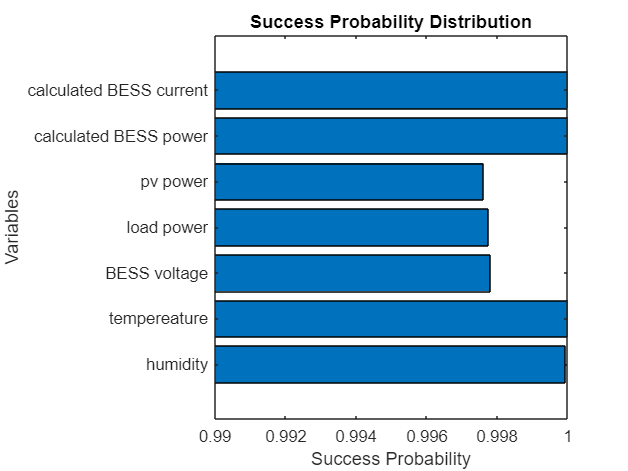

% create a cell array with the variable names
var_names = {'humidity', 'tempereature', 'BESS voltage', 'load power', ...
    'pv power', 'calculated BESS power', 'calculated BESS current'};

% plot the histogram
figure;
% create a vector with all the success probabilities
success_probs = [succes_probability_humidity, succes_probability_temperature, succes_probability_BESS_voltage, ...
    succes_probability_load_power, succes_probability_pv_power, succes_probability_calculated_BESS_power, ...
    succes_probability_calculated_BESS_current];

barh(success_probs)
set(gca,'yticklabel',var_names)

% add axis labels and title
xlabel('Success Probability')
ylabel('Variables')
title('Success Probability Distribution')
xlim([0.99 1]);

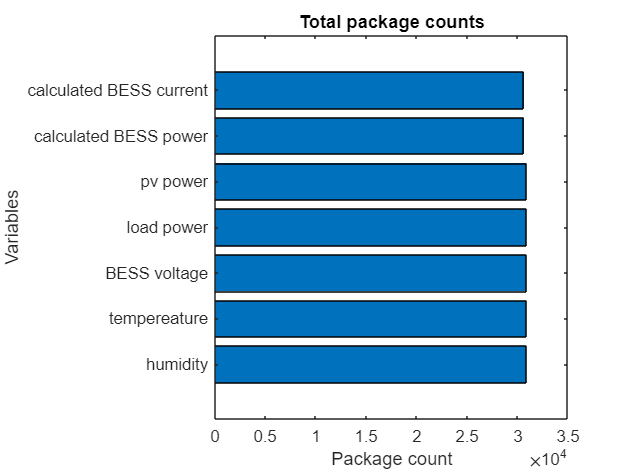


% create a vector with all the success probabilities
success_probs = [succes_probability_humidity, succes_probability_temperature, succes_probability_BESS_voltage, ...
    succes_probability_load_power, succes_probability_pv_power, succes_probability_calculated_BESS_power, ...
    succes_probability_calculated_BESS_current];

% plot the histogram
figure;

% create a vector with all the success probabilities
total_package_counts = [total_packages_humidity, total_packages_temperature, total_packages_BESS_voltage, ...
    total_packages_load_power, total_packages_pv_power, total_packages_BESS_power, ...
    total_packages_BESS_current];

barh(total_package_counts)
set(gca,'yticklabel',var_names)

% add axis labels and title
xlabel('Package count')
ylabel('Variables')
title('Total package counts')

**Conclusion**

In conclusion, the wireless device control system based on LoRa that we developed has proven to be highly successful, with a success rate far better than what was initially expected. The test that we conducted over a 12-hour period showed that the system was able to transmit and receive data with a high level of accuracy and reliability.

It should be noted, however, that the test was not conducted under extreme scenarios, and the devices were kept in close proximity to each other. Nonetheless, the results of the test were highly encouraging and demonstrate the potential of this system for use in a variety of settings and applications.

## **Appendix I: Functions**

function [data, data_timestamp_unix, data_corrupted, data_corrupted_timestamp_unix] = filter_data(csv_table, s_date, e_date, device_name, tag)
    data_timestamp_unix = [];
    data = [];
    data_corrupted_timestamp_unix = [];
    data_corrupted = [];
    %csv_table => imported .csv data
    %s_date => start filtering from -> [year,month,day,hour, minute, second]
    %e_date => filter until -> [year, month, day, hour, minute, second]
    %device_name => device name to filter
    % Create a datetime object using the specified values
    d_s = datetime(s_date(1), s_date(2), s_date(3), s_date(4), s_date(5), s_date(6));
    d_e = datetime(e_date(1), e_date(2), e_date(3), e_date(4), e_date(5), e_date(6));
    % Convert the datetime object to Unix time using posixtime function
    u_s = posixtime(d_s);
    u_e = posixtime(d_e);
    
    number_of_rows = height(csv_table);
    for row_no = 1:number_of_rows

        %check if device is the one that data is filtered for
        device = string(csv_table{row_no, 8});
        if device ~= device_name
            continue
        end
        %check if tag is the one that data is filtered for
        tag_candidate = string(csv_table{row_no, 10});
        if tag_candidate ~= tag
            continue
        end
        %check if record in between desired time interval
        d_data = datetime(csv_table{row_no, 1}, csv_table{row_no, 2}, csv_table{row_no, 3}, csv_table{row_no, 4}, csv_table{row_no, 5}, csv_table{row_no, 6});
        u_d = posixtime(d_data);
        if(u_d<u_s || u_d > u_e)
            continue
        end
        data_candidate = csv_table{row_no, 11};
        if isnan(data_candidate)
            data_corrupted = [ data_corrupted  data_candidate];
            data_corrupted_timestamp_unix = [data_corrupted_timestamp_unix (u_d-u_s)];
        else
            data = [data data_candidate];
            data_timestamp_unix = [data_timestamp_unix (u_d-u_s)];
        end
        

    end

end



